T_train = parquetread('jets_train_30000.parquet.gzip');
T_test  = parquetread('jets_test_10000.parquet.gzip');
T_train = movevars(T_train, 'is_signal', 'Before', 1);
T_test  = movevars(T_test,  'is_signal', 'Before', 1);
unique(T_train.is_signal)

ans = 2×1 int32 column vector
   0
   1


T_train.Properties.VariableNames(1:6)

ans = 1×6 cell array
    {'is_signal'}    {'E_0'}    {'px_0'}    {'py_0'}    {'pz_0'}    {'E_1'}


T_train = sortrows(T_train, 'is_signal');
T_test  = sortrows(T_test,  'is_signal');

G_train = groupsummary(T_train, 'is_signal')

G_train = 2×2 table
    is_signal    GroupCount
    _________    __________

        0          14907   
        1          15093   


G_test  = groupsummary(T_test, 'is_signal')

G_test = 2×2 table
    is_signal    GroupCount
    _________    __________

        0           4989   
        1           5011   



destFolder = fileparts('C:\Users\pankaj soni\MATLAB Drive\FileExchange\Deep Learning for Real-Time Top Quark Jet Tagging-1.2.0\solution.mlx');
destFile = fullfile(destFolder, 'jets_cleaned.mat');
copyfile(fullfile(tempdir, 'jets_cleaned.mat'), destFile);


## Jet-to-Image Conversion (corrected: T_jets -> T_train)

function y= Table_To_3DTensor(x)
y = x{:,2:4*35+1}';                
y = reshape(y,4,35,[]);              
y = pagetranspose(y);
end

%% Convert T_test into images for TestImagesFolder

% Recompute group counts for the test table
G_test = groupsummary(T_test, 'is_signal');

Jet_test = Table_To_3DTensor(T_test);
pT_test  = sqrt(Jet_test(:,2,:).^2 + Jet_test(:,3,:).^2);
eta_test = squeeze(asinh(Jet_test(:,4,:)./pT_test));
phi_test = squeeze(atan2(Jet_test(:,3,:),Jet_test(:,2,:)));

eta_test = eta_test - eta_test(1,:);
phi_test = phi_test - phi_test(1,:);

Nb = 37;
Xedges = linspace(-1.6,1.6,Nb+1);
Yedges = linspace(-1.6,1.6,Nb+1);

xGrp = discretize(eta_test, Xedges);
yGrp = discretize(phi_test, Yedges);
zGrp = repelem(1:size(Jet_test,3), size(eta_test,1));
V = rmmissing([pT_test(:) xGrp(:) yGrp(:) zGrp(:)]);
I_test = accumarray(V(:,2:4), V(:,1), [Nb, Nb, size(Jet_test,3)]);

Ia_test = zeros(Nb^2, size(Jet_test,3));
for n = 1:size(Jet_test,3)
    Ia_test(:,n) = reshape(I_test(:,:,n), Nb^2, 1);
    Ia_test(:,n) = circshift(Ia_test(:,n), ceil(length(Ia_test(:,n))/2) - find(Ia_test(:,n)==max(Ia_test(:,n))));
end
Ia_test = normalize(Ia_test, 'norm');
I_test = reshape(Ia_test, Nb, Nb, []);
I_test = zscore(I_test, 0, 3);

% Use a LOCAL folder to avoid the MATLAB Drive slowness/sync issue
workDir = tempdir;
testFolder1 = fullfile(workDir, 'TestImagesFolder', 'Background');
testFolder2 = fullfile(workDir, 'TestImagesFolder', 'TopJets');
mkdir(testFolder1);

mkdir(testFolder2);


g_test = min(G_test{1,2}, G_test{2,2});   % should be 5000 each for a balanced 10k test set

for aa = 1:g_test
    imwrite(I_test(:,:,aa),       fullfile(testFolder1, ['jet', sprintf('%d',aa), '.png']));
    imwrite(I_test(:,:,aa+g_test), fullfile(testFolder2, ['jet', sprintf('%d',aa), '.png']));
    if mod(aa, 500) == 0
        fprintf('Written %d / %d test image pairs\n', aa, g_test);
    end
end

Written 500 / 4989 test image pairs
Written 1000 / 4989 test image pairs
Written 1500 / 4989 test image pairs
Written 2000 / 4989 test image pairs
Written 2500 / 4989 test image pairs
Written 3000 / 4989 test image pairs
Written 3500 / 4989 test image pairs
Written 4000 / 4989 test image pairs
Written 4500 / 4989 test image pairs



disp('Done. TestImagesFolder is at:')

Done. TestImagesFolder is at:


disp(fullfile(workDir, 'TestImagesFolder'))

C:\Users\pankaj soni\AppData\Local\Temp\TestImagesFolder


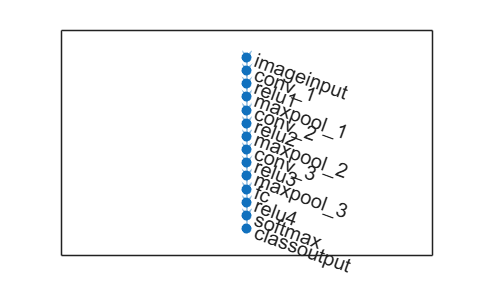


layers = [
    imageInputLayer([37 37 1],"Name","imageinput","Normalization","none")
    convolution2dLayer([4 4],64,"Name","conv_1","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([4 4],64,"Name","conv_2","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([4 4],64,"Name","conv_3","Padding","same","Stride",[2 2],"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu3")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(2,"Name","fc","WeightLearnRateFactor",0.1)
    reluLayer("Name","relu4")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

plot(layerGraph(layers));

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:29 |       44.53% |       44.84% |       2.9457 |       1.0524 |          0.0100 |
|       1 |          30 |       00:01:02 |       69.53% |       75.55% |       0.6057 |       0.6415 |          0.0100 |
|       1 |          50 |       00:01:04 |       81.25% |              |       0.6381 |              |          0.0100 |
|       1 |          60 |       00:01:05 |       60.94% |       69.14% |       0.6414 |       0.6219 |          0.0100 |
|       

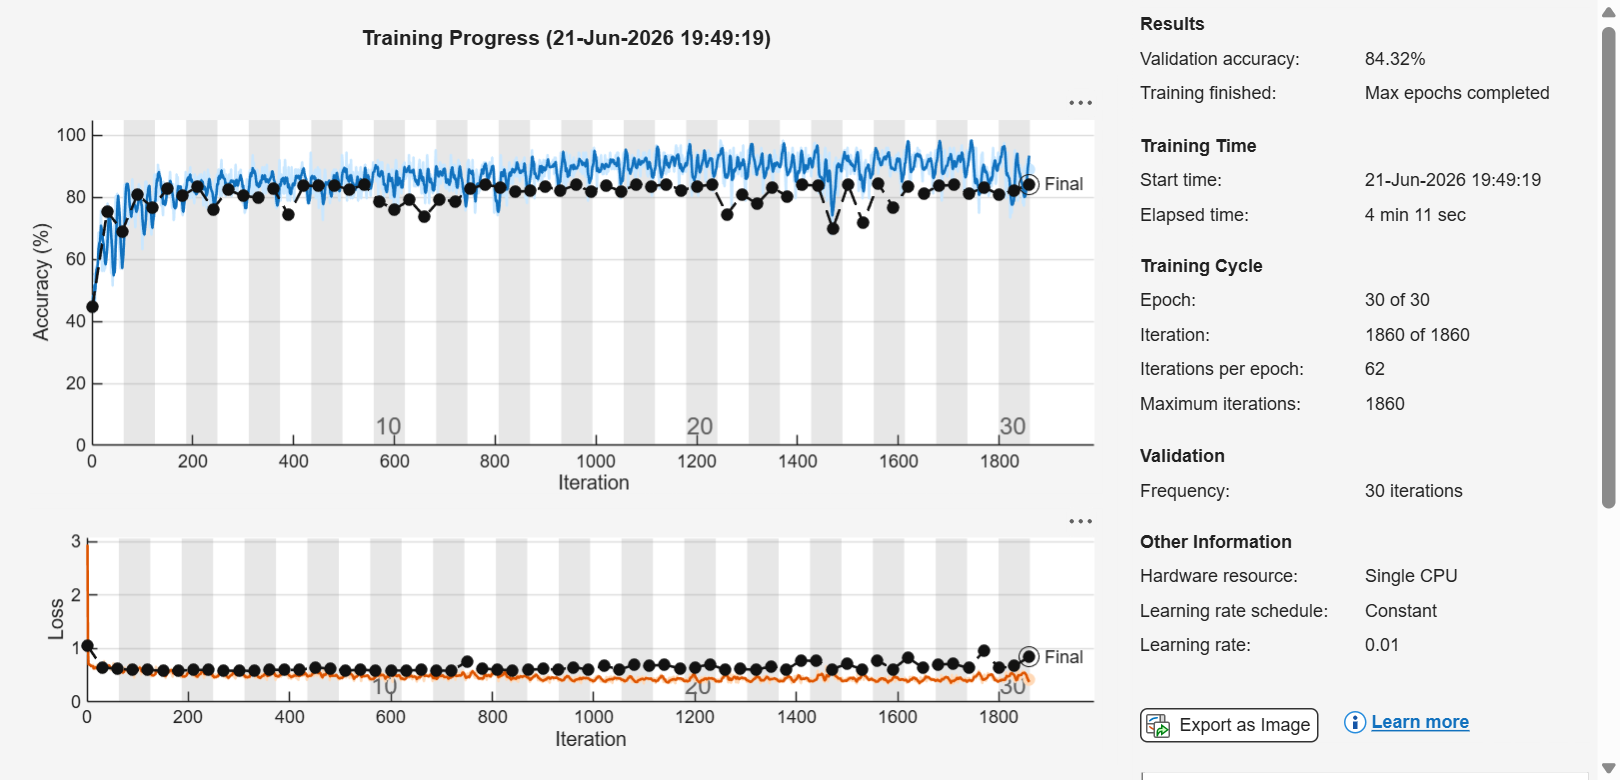


imageFolder = fullfile(tempdir,'TestImagesFolder');

imds = imageDatastore(imageFolder, .....
'IncludeSubfolders', true, ...
    'FileExtensions', '.png', ...
    'LabelSource', 'foldernames');
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

rng(0)

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 30, ...
    'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, ...
    'Plots', 'training-progress', ...
    'Verbose', true);

trainedNetwork_1 = trainNetwork(imdsTrain, layers, options);


save(fullfile(tempdir, 'trainedNetwork_JetTaggingCNN.mat'), 'trainedNetwork_1')

testimageFolder = fullfile(tempdir,'TestImagesFolder');
imds_test = imageDatastore(testimageFolder,'IncludeSubfolders',true,'FileExtensions','.png','LabelSource','foldernames');

numel(imds_test.Files)   % sanity check — should be close to 10,000

ans = 9978


labels_predicted = categorical(repmat("Background",1,numel(imds_test.Files)));
scores = zeros(numel(imds_test.Files),2);

for jj = 1:numel(imds_test.Files)
    [labels_predicted(jj), scores(jj,:)] = classify(trainedNetwork_1, readimage(imds_test,jj));
end

labels_true = imds_test.Labels;   % use the datastore's own labels instead of manually constructing them

C = confusionmat(labels_true, labels_predicted);
classification_accuracy = trace(C)/sum(sum(C))

classification_accuracy = 0.8638

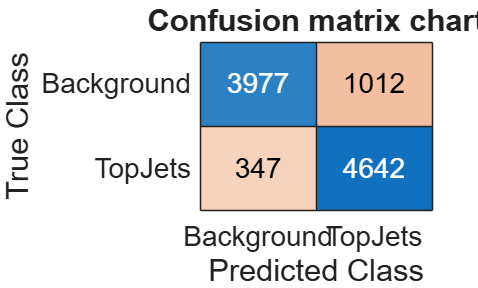

confusionchart(labels_true, labels_predicted, "title","Confusion matrix chart",'fontsize',14);

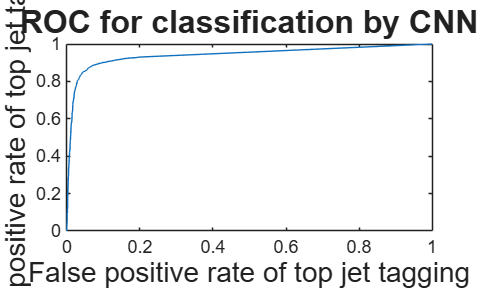

classOrder = trainedNetwork_1.Layers(end).Classes;
topJetsCol = find(classOrder == 'TopJets');

labels_true = categorical(imds_test.Labels, {'Background','TopJets'});
[X,Y,~,AUC] = perfcurve(labels_true, scores(:,topJetsCol), 'TopJets');

plot(X,Y)
xlabel('False positive rate of top jet tagging','fontsize',14);
ylabel('True positive rate of top jet tagging','fontsize',14);
title('ROC for classification by CNN','fontsize',16)

AUC

AUC = 0.9418


% Check installed add-ons for the required support package
addons = matlab.addons.installedAddons;
disp(addons.Name);

    "Signal Processing Toolbox"
    "Antenna Toolbox"
    "Aerospace Blockset"
    "DSP System Toolbox"
    "Aerospace Toolbox"
    "Communications Toolbox"
    "Deep Learning Toolbox"
    "Deep Learning HDL Toolbox"
    "Satellite Communications Toolbox"
    "Simulink"
    "Statistics and Machine Learning Toolbox"
    "UAV Toolbox"




% After installing the "Deep Learning HDL Toolbox Support Package for AMD FPGA and SoC Devices"
% (install via MATLAB Add-On Explorer), create the target as before:
hTarget = dlhdl.Target('Xilinx','Interface','Ethernet');

Error using dlhdl.Target (line 58)
Attempt to create a Target for vendor 'Xilinx'. The 'Deep Learning HDL Toolbox Support Package for AMD FPGA and SoC Devices' support package has not been installed.

hTarget = dlhdl.Target('Xilinx','Interface','Ethernet');
hW=dlhdl.Workflow('Network',trainedNetwork_1,  'Bitstream', 'zcu102_single','Target',hTarget);
dn = hW.compile('InputFrameNumberLimit',15)